% Define the filter order and cutoff frequency
order = 4;
cutoffFreq = 0.2;

% Design the Butterworth filter
[b, a] = butter(order, cutoffFreq);

% Print the filter coefficients
disp("Filter Coefficients:");

Filter Coefficients:


disp("Numerator (b):");

Numerator (b):


disp(b);

    0.0048    0.0193    0.0289    0.0193    0.0048



disp("Denominator (a):");

Denominator (a):


disp(a);

    1.0000   -2.3695    2.3140   -1.0547    0.1874



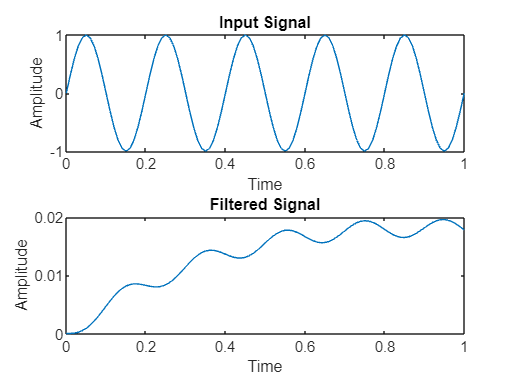

% Define the filter coefficients
order = 2; % filter order
cutoff_freq = 0.2; % cutoff frequency

% Generate an input signal
t = 0:0.01:1; % time vector
x = sin(2*pi*5*t); % input signal (5 Hz sine wave)

% Initialize the output signal
y = zeros(size(x));

% Compute the filter coefficients
fs = 1/(t(2)-t(1)); % sampling frequency
nyquist_freq = fs/2; % Nyquist frequency
cutoff = cutoff_freq/nyquist_freq; % normalized cutoff frequency
[b, a] = butter(order, cutoff); % compute filter coefficients

% Apply the filter to the input signal
for n = 1:length(x)
    y(n) = b(1)*x(n);
    for k = 2:length(b)
        if n-k+1 > 0
            y(n) = y(n) + b(k)*x(n-k+1);
        end
    end
    for k = 2:length(a)
        if n-k+1 > 0
            y(n) = y(n) - a(k)*y(n-k+1);
        end
    end
end

% Plot the input and filtered signals
subplot(2,1,1);
plot(t, x);
title('Input Signal');
xlabel('Time');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y);
title('Filtered Signal');
xlabel('Time');
ylabel('Amplitude');